clear

altCreaseDat = readmatrix("altDatShastN20Inst500.txt");
X=(1:length(altCreaseDat));

% Fit line
pol = polyfit(X, altCreaseDat, 1);
b = exp(pol(2))

b = 0.8040

a = pol(1)

a = 0.9041

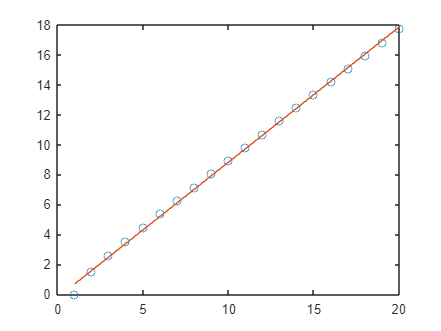


% y values for the line
yfit = polyval(pol, X);

% Plot
plot(X,altCreaseDat, 'o');
hold on;
plot(X, yfit, '-');

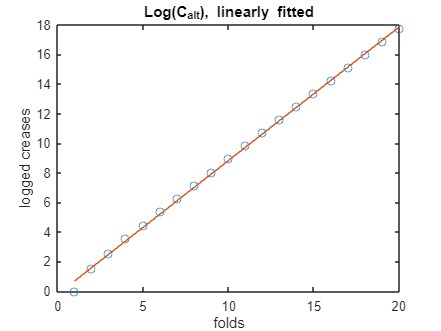


xlabel("folds");
ylabel("logged creases");
title("Log(C_{alt}), linearly fitted");
hold off;